# Exergy Analysis Demo

Use `ExergyAnalysys` function to obtain the exergy balances and Table FP for one state of the plant

#### Read the Data Model

file="C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\orcvcr\orcvcr_model.xlsx";
data=ReadDataModel(file);

#### Select the state of the plant to analyze

states=convertCharsToStrings(data.States);
state=convertStringsToChars(States(6));

#### Get the exergy values 

res=ThermoeconomicState(data,'State',state,'Show',true);

Flows Exergy Table

Key   From     To             B(kW)
————————————————————————————————————
B1    BLR_P1   TRB_F1        1172.0
B2    TRB_F1   CND_F1         599.8
B3    CND_F1   PMP_P1         531.5
B4    PMP_P1   BLR_P1         555.4
B5    CND_F2   VEXP_F1        220.7
B6    VEXP_F1  EVAP_F1        194.0
B7    EVAP_F1  CMP_P1          59.6
B8    CMP_P1   CND_F2         244.5
WT    TRB_P1   GEN_F1         462.6
WC    GEN_F1   CMP_F1         230.0
WP    GEN_P1   PMP_F1          27.9
QBLR  ENV_R1   BLR_F1         872.1
QEVP  EVAP_P1  ENV_O1          64.2
WN    GEN_P1   ENV_O2         200.0
QEXP  VEXP_P1  ENV_W1          26.7
QCND  CND_P1   ENV_W2          92.0


Productive Groups Exergy Table

Key            E(kW)     ET(kW)
————————————————————————————————
BLR_F1         872.1      872.1
BLR_P1         616.6     1172.0
TRB_F1         572.2     1172.0
TRB_P1         462.6      462.6
PMP_F1          27.9       27.9
PMP_P1          23.9      555.4
CMP_F1         230.0      230.0
CMP_P1  

#### Show the Diagram FP

Show the Diagram FP as graph using `ShowGraph` function, and as Matlab table using `ShowTable` function

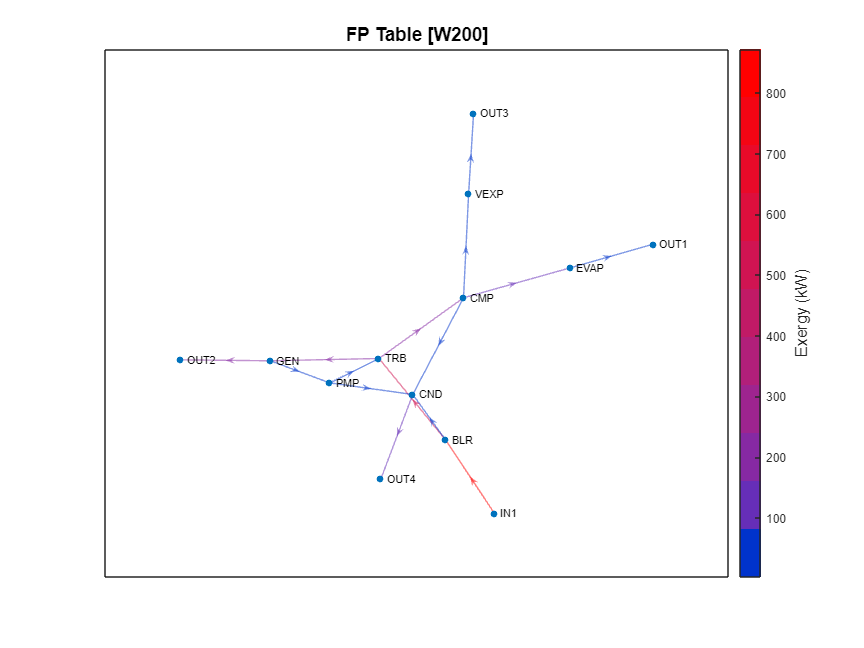

ShowGraph(res)

tbl=ShowTable(res.Tables.tfp,'View','NONE','ExportAs','TABLE')

tbl = 10×10 table
              BLR      TRB       PMP     CMP     EVAP      GEN     VEXP     CND       ENV      Total 
             _____    ______    _____    ___    ______    _____    ____    ______    ______    ______

    BLR          0    550.85        0      0         0        0       0    65.751         0     616.6
    TRB          0         0        0    230         0    232.6       0         0         0     462.6
    PMP          0    21.351        0      0         0        0       0    2.5486         0      23.9
    CMP          0         0        0      0    134.43        0